# Bridge of Doom

## Exercise 36.1

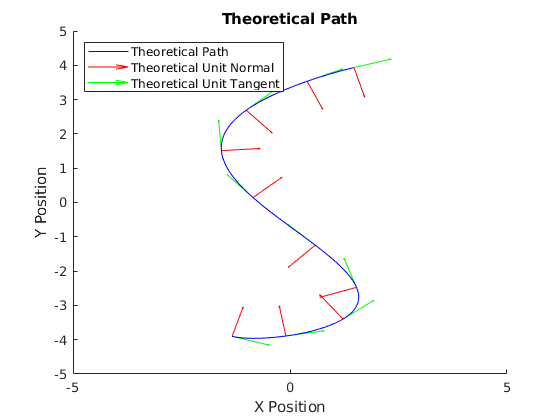

clc, clear, clf
syms beta t
assume(beta, {'real', 'positive'});
assume(t, {'real', 'positive'});

global r T_hat N_hat beta_num V_L V_R t_num

r_i = 4*(.3960*cos(2.65*((beta*t)+1.4)));
r_j = -4 * (.99*sin((beta*t)+1.4));
r_k = 0*t;

r = [r_i, r_j, r_k];

dr_dt = simplify(diff(r,t));
T_hat = simplify(dr_dt./norm(dr_dt));

dT_dt = simplify(diff(T_hat, t));
N_hat = simplify(dT_dt./norm(dT_dt));

beta_num = .2;

t_num = linspace(0, 3.2 / beta_num, 100);
x_num = linspace(0, 3.2 / beta_num, 10);

figure
title('Theoretical Path')
hold on
for n=1:length(t_num)
    r_num(n,:) = double(subs(r, {beta, t}, {beta_num, t_num(n)}));
    T_hat_num(n,:) = double(subs(T_hat, {beta, t}, {beta_num, t_num(n)}));
    N_hat_num(n,:) = double(subs(N_hat, {beta, t}, {beta_num, t_num(n)}));
    
    p1 = plot(r_num(:,1), r_num(:,2), 'blue', 'DisplayName', 'Theoretical Path'); axis([-5 5 -5 5]);
    
    if (ismember(t_num(n), x_num))
        q1 = quiver(r_num(n,1), r_num(n,2), N_hat_num(n,1), N_hat_num(n,2), 'red', 'DisplayName', 'Theoretical Unit Normal');
        q2 = quiver(r_num(n,1), r_num(n,2), T_hat_num(n,1), T_hat_num(n,2), 'green', 'DisplayName', 'Theoretical Unit Tangent');
    end
end
legend([p1 q1 q2], 'Location', 'northwest')
xlabel('X Position')
ylabel('Y Position')
hold off

## Exercise 36.2

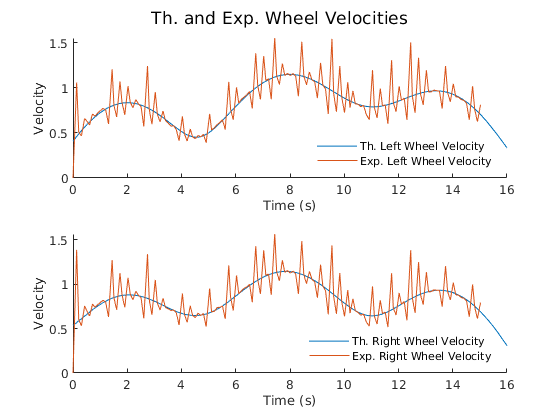

clf
omega = simplify(cross(T_hat, dT_dt));
V = simplify(norm(dr_dt));
d = .235;

V_L = simplify(V - omega(:,3)*d/2);
V_R = simplify(V + omega(:,3)*d/2);

V_L = subs(V_L, {beta}, {beta_num});
V_R = subs(V_R, {beta}, {beta_num});

% Experimental
load bod.mat

% Double click on `bod.mat` to load dataset
data = dataset(9:end-10,:);
time = (data(:,1) - data(1,1));
pos_l = data(:,2);
pos_r = data(:,3);
dt = diff(time);

exp_r = zeros(length(time)-1,2);
exp_theta = zeros(length(time)-1,1);

r_0 = double(subs(r, {beta, t}, {beta_num, 0}));
exp_r(1,1) = r_0(:,1);
exp_r(1,2) = r_0(:,2);

t_hat_0 = double(subs(T_hat, {beta, t}, {beta_num, 0}));

exp_theta(1) = atan2(t_hat_0(2), t_hat_0(1));

clf
figure

t_num = linspace(0, 3.2 / beta_num, 100);
x_num = linspace(0, 3.2 / beta_num, 10);

exp_V_L = diff(pos_l) ./ diff(time);
exp_V_R = diff(pos_r) ./ diff(time);

fig = figure;
sgtitle('Th. and Exp. Wheel Velocities')
subplot(2,1,1)
hold on
fplot(V_L, 'DisplayName', 'Th. Left Wheel Velocity')
plot(time(1:end-1), exp_V_L, 'DisplayName', 'Exp. Left Wheel Velocity')
xlabel('Time (s)')
ylabel('Velocity')
legend('Location', 'southeast')
legend('boxoff')
hold off

subplot(2,1,2)
hold on
fplot(V_R, 'DisplayName', 'Th. Right Wheel Velocity')
plot(time(1:end-1), exp_V_R, 'DisplayName', 'Exp. Right Wheel Velocity')
xlabel('Time (s)')
ylabel('Velocity')
legend('Location', 'southeast')
legend('boxoff')
hold off

xlim([0 3.2 / beta_num])

## Exercise 36.3

linear_velocity = (V_L + V_R) / 2

$$linear\_velocity = \frac{99\,\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}}}{6250}$$

angular_velocity = (V_R - V_L) / d

$$angular\_velocity = -\frac{53\,\left(182500\,\cos\left(\frac{7\,t}{100}+\frac{49}{100}\right)+764917\,\cos\left(\frac{33\,t}{100}+\frac{231}{100}\right)+327837\,\cos\left(\frac{73\,t}{100}+\frac{511}{100}\right)+82500\,\cos\left(\frac{113\,t}{100}+\frac{791}{100}\right)-205057\,\cos\left(\frac{139\,t}{100}+\frac{973}{100}\right)-92697\,\cos\left(\frac{179\,t}{100}+\frac{1253}{100}\right)\right)}{4\,{\left(2500\,\cos\left(\frac{2\,t}{5}+\frac{14}{5}\right)-2809\,\cos\left(\frac{53\,t}{50}+\frac{371}{50}\right)+5309\right)}^{2}}$$

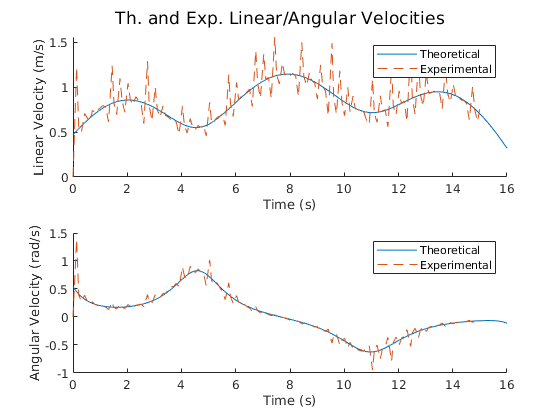

exp_V = .5*(exp_V_L + exp_V_R);
exp_omega = (1/d)*(exp_V_R - exp_V_L);

figure
sgtitle('Th. and Exp. Linear/Angular Velocities')
xlim([0 3.2/beta_num])
ylim([-1 2])

subplot(2,1,1)
hold on
fplot(linear_velocity, 'DisplayName', 'Theoretical')
plot(time(1:end-1), exp_V,'--', 'DisplayName', 'Experimental')
xlabel('Time (s)')
ylabel('Linear Velocity (m/s)')
legend()
hold off

subplot(2,1,2)
hold on
fplot(angular_velocity, 'DisplayName', 'Theoretical')
plot(time(1:end-1), exp_omega,'--', 'DisplayName', 'Experimental')
xlabel('Time')
xlabel('Time (s)')
ylabel('Angular Velocity (rad/s)')
legend()
hold off

## Exercise 36.4

See `cross_BOD.m`. Video at [https://youtu.be/FyuYOvEM_9E.](https://youtu.be/FyuYOvEM_9E.) 

## Exercise 36.5

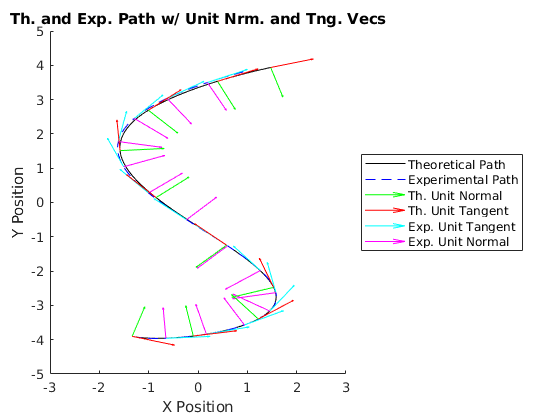

exp_T_hat = zeros(length(time)-1,2);
exp_N_hat = zeros(length(time)-1,2);

for s = 1:(length(time)-1)
    exp_r(s+1, 1) = exp_r(s,1) + exp_V(s)*cos(exp_theta(s))*dt(s);
    exp_r(s+1, 2) = exp_r(s,2) + exp_V(s)*sin(exp_theta(s))*dt(s);
    exp_theta(s+1) = exp_theta(s) + exp_omega(s) * dt(s);
    exp_T_hat(s,1) = cos(exp_theta(s));
    exp_T_hat(s,2) = sin(exp_theta(s));
    
    normal_adj = pi/2;
    if (exp_V_L(s) > exp_V_R(s))
        normal_adj = normal_adj*-1;
    end
    exp_N_hat(s,1) = cos(exp_theta(s) + normal_adj);
    exp_N_hat(s,2) = sin(exp_theta(s) + normal_adj);
end

clf
figure
hold on
p1 = plot(r_num(:,1), r_num(:,2), 'black', 'DisplayName', 'Theoretical Path');
p2 = plot(exp_r(:,1), exp_r(:,2), '--blue', 'DisplayName', 'Experimental Path');

for m=2:10:length(time)-1
    q3 = quiver(exp_r(m,1), exp_r(m,2), exp_T_hat(m,1), exp_T_hat(m,2), 'cyan', 'DisplayName', 'Exp. Unit Tangent');
    q4 = quiver(exp_r(m,1), exp_r(m,2), exp_N_hat(m,1), exp_N_hat(m,2), 'magenta', 'DisplayName', 'Exp. Unit Normal');
end

for n=1:length(t_num)
    if (ismember(t_num(n), x_num))
        q1 = quiver(r_num(n,1), r_num(n,2), N_hat_num(n,1), N_hat_num(n,2), 'green', 'DisplayName', 'Th. Unit Normal');
        q2 = quiver(r_num(n,1), r_num(n,2), T_hat_num(n,1), T_hat_num(n,2), 'red', 'DisplayName', 'Th. Unit Tangent');
    end
end

legend([p1 p2 q1 q2 q3 q4], 'Location', 'eastoutside')
axis([-3 3 -5 5])
title("Th. and Exp. Path w/ Unit Nrm. and Tng. Vecs")
xlabel('X Position')
ylabel('Y Position')
hold off

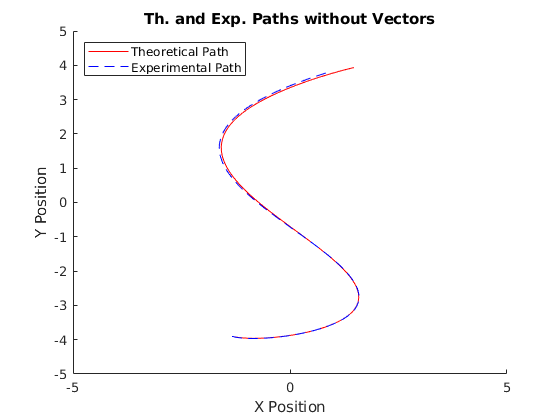

figure
hold on
title('Th. and Exp. Paths without Vectors')
p1 = plot(r_num(:,1), r_num(:,2), 'red', 'DisplayName', 'Theoretical Path');
p2 = plot(exp_r(:,1), exp_r(:,2), '--blue', 'DisplayName', 'Experimental Path');
axis([-5 5 -5 5])
legend('Location', 'northwest')
xlabel('X Position')
ylabel('Y Position')
hold off

## Exercise 36.6

For write up, see `README.md` or [https://github.com/jack-greenberg/QEA-Bridge-of-Doom/blob/master/README.md](https://github.com/jack-greenberg/QEA-Bridge-of-Doom/blob/master/README.md).